cla reset;

**1) Рассчитаем в программе Mathcad линейчатый спектр периодической  последовательности косинусоидальных импульсов при Θ = 𝑈𝐺 = 30°: **

N = 20;
AM = 1;
UG = 30;


$$\begin{array}{l}
A_k =\frac{2}{\pi }\int_0^{\pi } Ф\left(x\right)\cdot \cos \left(k\cdot x\right)dx\\
A_0 =\frac{1}{\pi }\int_0^{\pi } Ф\left(x\right)dx\\
{\mathrm{AD}}_k =\kappa \cdot \log \left(\frac{|A_k |}{A_1 }\right)
\end{array}$$


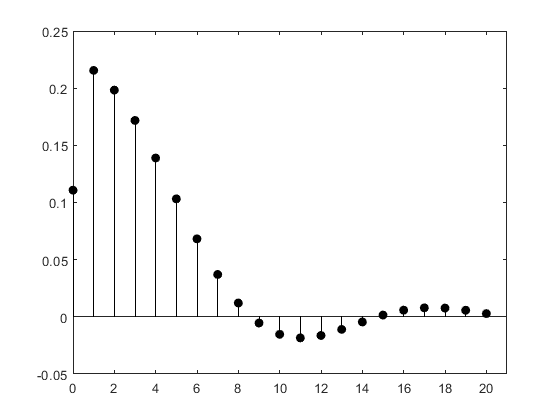

ans = table
         A     
    ___________

    1×21 double


ans = table
        AD     
    ___________

    1×21 double


spectrplot(N, AM, UG, "plot2_1.jpg")

**2) Рассчитаем в программе Mathcad линейчатый спектр периодической последовательности косинусоидальных импульсов при Θ = 𝑈𝐺 = 90°: **

ans = table
         A     
    ___________

    1×21 double


ans = table
        AD     
    ___________

    1×21 double


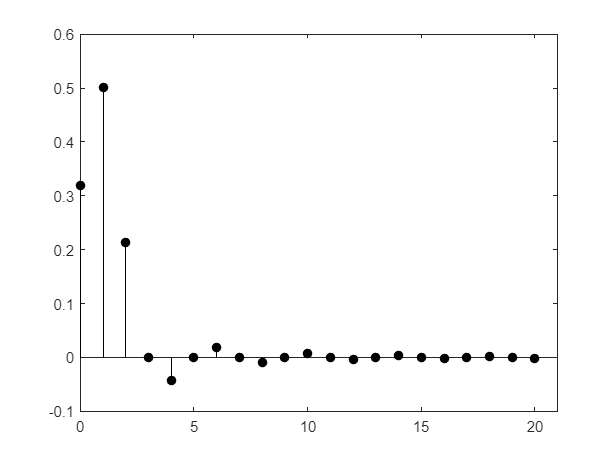

UG = 90;
spectrplot(N, AM, UG, "plot2_2.jpg")

**3) Рассчитаем в программе Mathcad линейчатый спектр периодической последовательности косинусоидальных импульсов при Θ = 𝑈𝐺 = 120°: **

ans = table
         A     
    ___________

    1×21 double


ans = table
        AD     
    ___________

    1×21 double


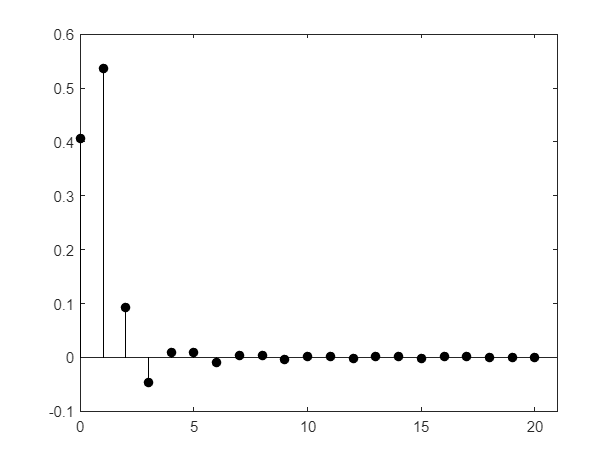

UG = 120;
spectrplot(N, AM, UG, "plot2_3.jpg")

function spectrplot(N, AM, UG, filename)
k = 0:N;
U = UG * (pi / 180);
A = Ak(N, U, AM);
table(A)
AD = 8.684 * log(abs(A)/A(2));
table(AD)
stem(k, A, 'LineStyle','-', 'Color','black', 'MarkerFaceColor','black');
xlim([0 21]);
saveas(gcf, filename);
end

function A = Ak(N, U, AM)
    p = zeros(1, (N + 1));
    for k = 0:N
        if k == 0
            ak = A0(U, AM);
            p(k + 1) = ak;
            continue;
        end
        ak = 0;
        for i = 0:0.001:pi
            y = F(i, U, AM);
            ak = ak + y * cos(k * i);
        end
        ak = (2/pi)*ak/1000;
        p(k +1) = ak;
    end
    A = p;
end

function z = A0(U, AM)
    z = 0;
    for i = 0:0.001:pi
        y = F(i, U, AM);
        z = z + y;
    end
    z = (1/pi)*z/1000;
    return;
end

function y = F(x, U, AM)
    if abs(x) <= U
        y = AM * ((cos(x) - cos(U))/(1 - cos(U)));
        return;
    end
    if isequal((U <= abs(x)), (abs(x) <= pi))
        y = 0;
        return;
    end
end